clc;clear all;close all;
% m1=0.75;
% m2=0.5;
% P1=80;
% P2=50;
% k1=100;
% k2=100;
A=[1 2; -3 -5];
B=[0 1 1;1 1 0]

B =      0     1     1
     1     1     0


C=[eye(2)]

C =      1     0
     0     1


D=[zeros(2,3)]

D =      0     0     0
     0     0     0



Q1=diag([100 100])

Q1 =    100     0
     0   100


Q2=diag([10000 10000])

Q2 =        10000           0
           0       10000



R1=diag([0.1 0.1 0.1])

R1 =     0.1000         0         0
         0    0.1000         0
         0         0    0.1000


R2=diag([0.1 0.1 0.1])

R2 =     0.1000         0         0
         0    0.1000         0
         0         0    0.1000



K1=lqr(A,B,Q1,R1)

K1 =    -6.1965   21.8013
   19.6085   15.6048
   25.8050   -6.1965


K2=lqr(A,B,Q2,R2)

K2 =   -66.4768  246.1281
  183.8685  179.6513
  250.3453  -66.4768



Kr1=pinv(-(C-D*K1)*(A-B*K1)^-1*B+D)

Kr1 =    -3.8632   25.8013
   20.2752   16.6048
   24.1384   -9.1965


Kr2=pinv(-(C-D*K2)*(A-B*K2)^-1*B+D)

Kr2 =   -64.1435  250.1281
  184.5351  180.6513
  248.6786  -69.4768



GCL1=ss(A-B*K1,B*Kr1,C-D*K1,D*Kr1)

GCL1 =
 
  A = 
           x1      x2
   x1  -44.41  -7.408
   x2  -16.41  -42.41
 
  B = 
          u1     u2
   x1  44.41  7.408
   x2  16.41  42.41
 
  C = 
       x1  x2
   y1   1   0
   y2   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.


GCL2=ss(A-B*K2,B*Kr2,C-D*K2,D*Kr2)

GCL2 =
 
  A = 
           x1      x2
   x1  -433.2  -111.2
   x2  -120.4  -430.8
 
  B = 
          u1     u2
   x1  433.2  111.2
   x2  120.4  430.8
 
  C = 
       x1  x2
   y1   1   0
   y2   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.



UGCL1=ss(A-B*K1,B*Kr1,-K1,Kr1)

UGCL1 =
 
  A = 
           x1      x2
   x1  -44.41  -7.408
   x2  -16.41  -42.41
 
  B = 
          u1     u2
   x1  44.41  7.408
   x2  16.41  42.41
 
  C = 
           x1      x2
   y1   6.197   -21.8
   y2  -19.61   -15.6
   y3  -25.81   6.197
 
  D = 
           u1      u2
   y1  -3.863    25.8
   y2   20.28    16.6
   y3   24.14  -9.197
 
Continuous-time state-space model.


UGCL2=ss(A-B*K2,B*Kr2,-K2,Kr2)

UGCL2 =
 
  A = 
           x1      x2
   x1  -433.2  -111.2
   x2  -120.4  -430.8
 
  B = 
          u1     u2
   x1  433.2  111.2
   x2  120.4  430.8
 
  C = 
           x1      x2
   y1   66.48  -246.1
   y2  -183.9  -179.7
   y3  -250.3   66.48
 
  D = 
           u1      u2
   y1  -64.14   250.1
   y2   184.5   180.7
   y3   248.7  -69.48
 
Continuous-time state-space model.


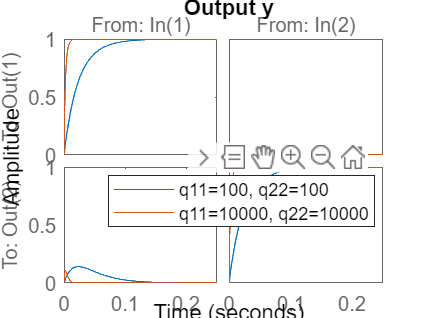


step(GCL1);hold on;
step(GCL2);
title('Output y')
legend('q11=100, q22=100','q11=10000, q22=10000')

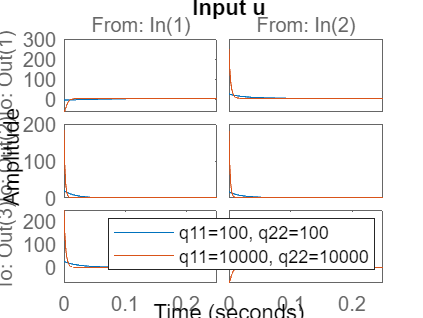

figure
step(UGCL1);hold on;
step(UGCL2);
title('Input u')
legend('q11=100, q22=100','q11=10000, q22=10000')

%En una sola gráfica:
GCL1=ss(A-B*K1,B*Kr1,[C-D*K1;-K1],[D*Kr1;Kr1])


GCL1 =
 
  A = 
           x1      x2
   x1  -44.41  -7.408
   x2  -16.41  -42.41
 
  B = 
          u1     u2
   x1  44.41  7.408
   x2  16.41  42.41
 
  C = 
           x1      x2
   y1       1       0
   y2       0       1
   y3   6.197   -21.8
   y4  -19.61   -15.6
   y5  -25.81   6.197
 
  D = 
           u1      u2
   y1       0       0
   y2       0       0
   y3  -3.863    25.8
   y4   20.28    16.6
   y5   24.14  -9.197
 
Continuous-time state-space model.


GCL2=ss(A-B*K2,B*Kr2,[C-D*K2;-K2],[D*Kr2;Kr2])


GCL2 =
 
  A = 
           x1      x2
   x1  -433.2  -111.2
   x2  -120.4  -430.8
 
  B = 
          u1     u2
   x1  433.2  111.2
   x2  120.4  430.8
 
  C = 
           x1      x2
   y1       1       0
   y2       0       1
   y3   66.48  -246.1
   y4  -183.9  -179.7
   y5  -250.3   66.48
 
  D = 
           u1      u2
   y1       0       0
   y2       0       0
   y3  -64.14   250.1
   y4   184.5   180.7
   y5   248.7  -69.48
 
Continuous-time state-space model.


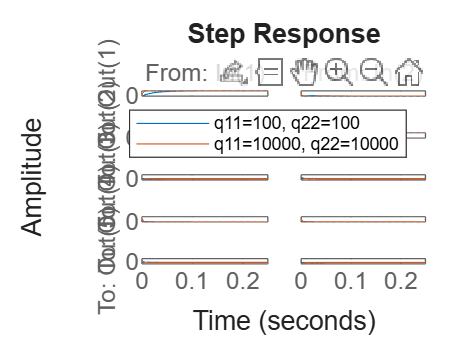

figure
step(GCL1);hold on;
step(GCL2);
legend('q11=100, q22=100','q11=10000, q22=10000')